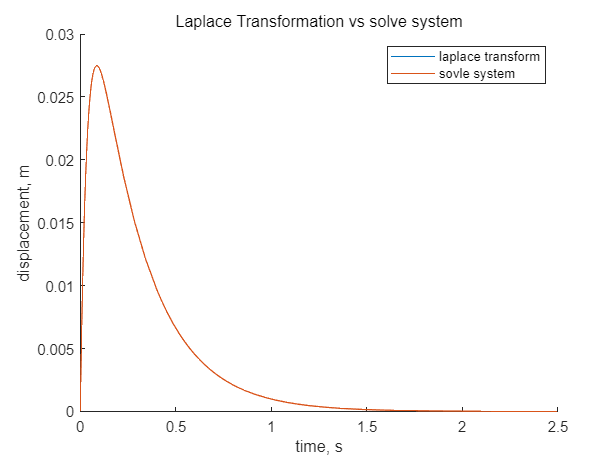

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 과도 감쇠의 경우 시스템의 응답을 라플라스 변환을 통해 계산

m = 1; k = 100; zeta = 1.5; c = 30;
Wn = sqrt(k/m);

% laplace transform
syms s
X_s = 1/(m*(s^2+2*zeta*Wn*s+Wn^2));
ft = ilaplace(X_s);

% solve system of differential equation
syms x(t)
eqn = m*diff(x,t,2)+c*diff(x,t)+k*x == 2*dirac(t);
Dx = diff(x, t);
f = dsolve(eqn, [x(0)==0, Dx(0)==0]);

% plot
hold on
fplot(ft, [0, 2.5]);
fplot(f, [0, 2.5]);
hold off
title('Laplace Transformation vs solve system');
xlabel('time, s');
ylabel('displacement, m');
axis([0, 2.5, 0, 0.03]);
legend('laplace transform', 'sovle system');